# SCR grand average for Study 2 data

Stimulus-locked grand average. For each trial, a baseline was created by averaging physiological time-series data from 3 seconds before the thermal stimulation onset.  A stimulus-locked physiological response was generated by subtracting the baseline value from the data in the 20-second period after the stimulation onset. 

## 1. Checking the data

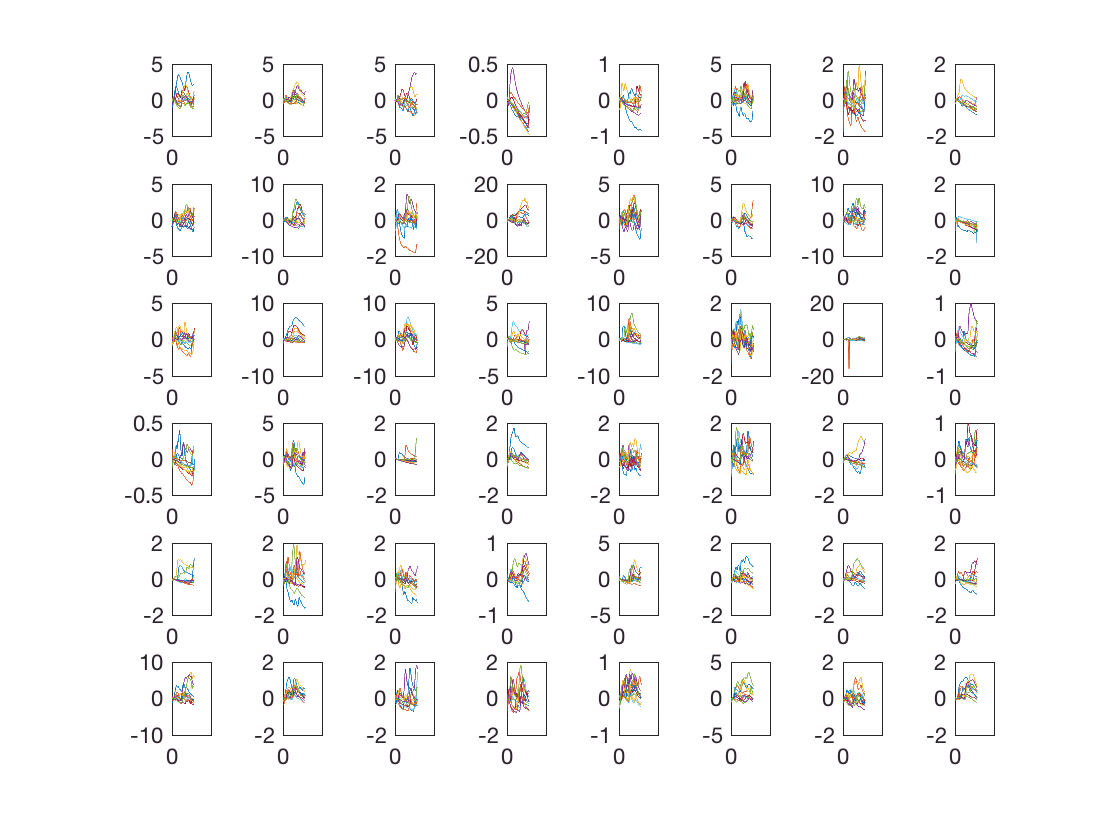

close all;
clear;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../marianne_data/CT_SCR_TempSort_Wani.mat');

% first 6 columns are 47 degrees
% next 3 are 48
% the last 3 are 49

% Sanity check
figure;
for i = 1:numel(Main_Present_SCR)
    subplot(6,8,i)
    plot(Main_Present_SCR{i})
end

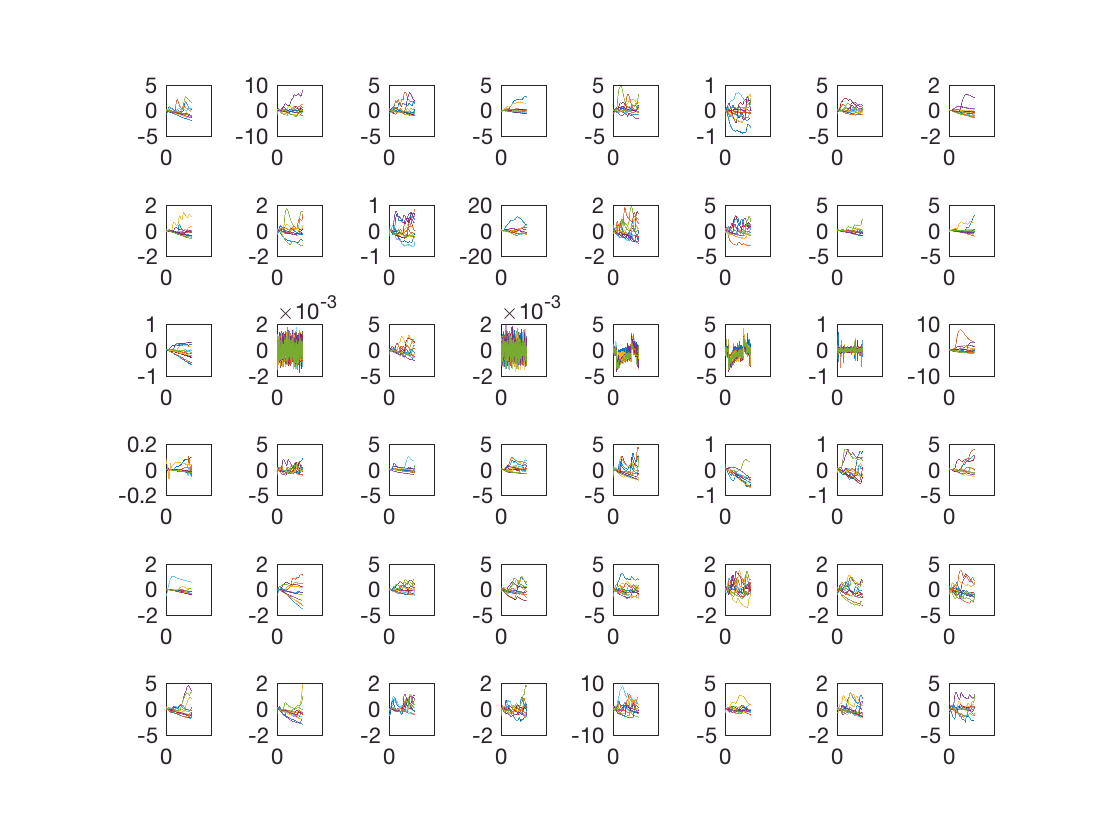


% remove big drop (outlier)
Main_Present_SCR{23}(:,9) = NaN(575,1);

figure;
for i = 1:numel(Main_Present_SCR)
    subplot(6,8,i)
    plot(Part_Present_SCR{i})
end

## 2. Data cleaning and formatting


%% There are subjects with tech errors
bad_subjects = [119,122,123,124,126,127,134];
bad_subj_idx = find(ismember(cat(2,CT_Subs{:,1}), bad_subjects));
good_subj_idx = find(~ismember(cat(2,CT_Subs{:,1}), bad_subjects));

% Get average signal for each temp 
clear signal_m;
k = 0;
for i = 1:numel(Main_Present_SCR)
    
    signal_m.main{1}(i,:) = nanmean(Main_Present_SCR{i}(:,1:6),2)';
    signal_m.main{2}(i,:) = nanmean(Main_Present_SCR{i}(:,7:9),2)';
    signal_m.main{3}(i,:) = nanmean(Main_Present_SCR{i}(:,10:12),2)';

    if ~any(ismember(bad_subjects, CT_Subs{i,1}))
        k = k + 1;
        signal_m.partner{1}(k,:) = nanmean(Part_Present_SCR{i}(:,1:6),2)';
        signal_m.partner{2}(k,:) = nanmean(Part_Present_SCR{i}(:,7:9),2)';
        signal_m.partner{3}(k,:) = nanmean(Part_Present_SCR{i}(:,10:12),2)';
    end
end

## 3. All temperature (Main); SCR grand average

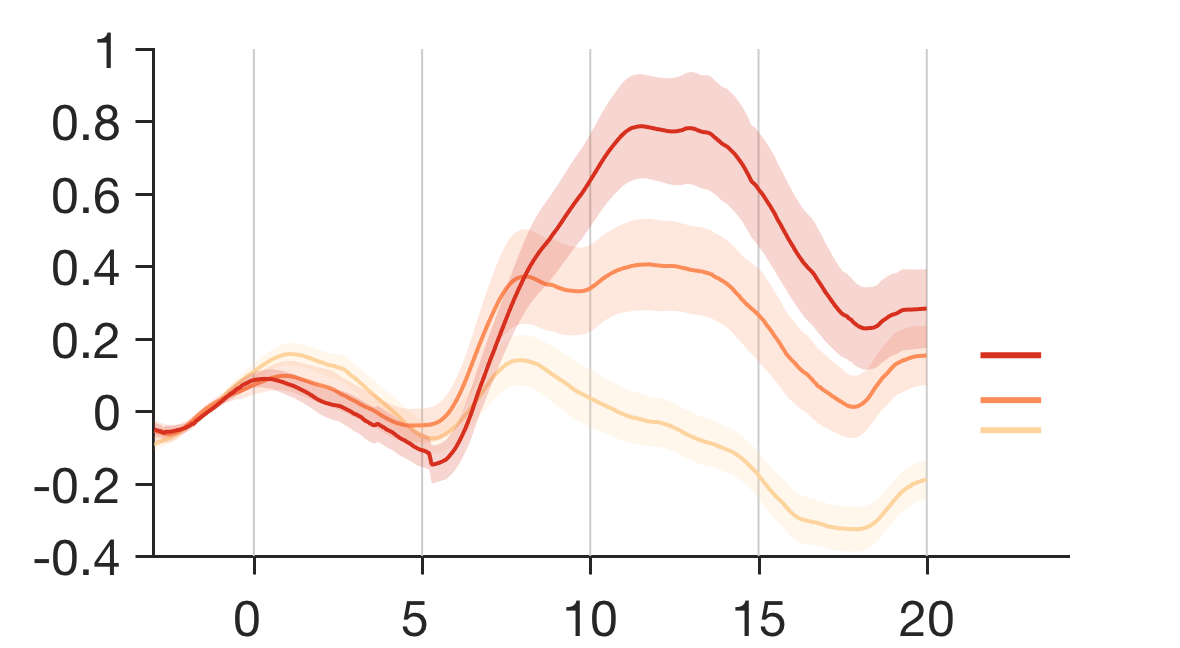

close all;
figdir = '../figures';

x = 1:575;
create_figure('shading');
cols = [0.9922    0.8314    0.6196
    0.9882    0.5529    0.3490
    0.8431    0.1882    0.1216];

for i = (3:5:24)*25
    line([i i], [-.5 1], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:3
    hold on;
    wani_plot_shading(x, mean(signal_m.main{i}), ste(signal_m.main{i}), 'color', cols(i,:), 'alpha', .2);
    line([615 660], repmat(median(mean(signal_m.main{i},2)), 1, 2), 'color', cols(i,:), 'linewidth', 3)
end


set(gcf, 'position', [50   126   600   324]);
set(gca, 'xlim', [0 680], 'ylim', [-.4 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:25)*25, 'ytick', -.4:.2:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);

savename = fullfile(figdir, 'Study2_Temp_all_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## 4. All temperature (Partner); SCR grand average

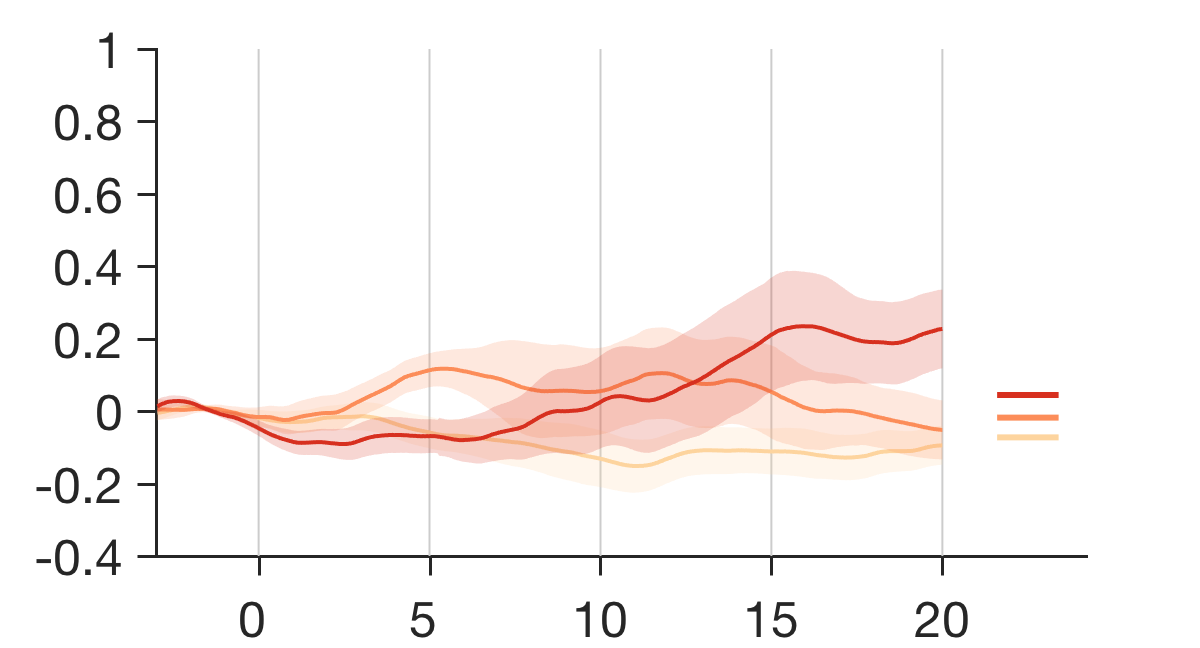

close all;
figdir = '../figures';

x = 1:575;
create_figure('shading');

for i = (3:5:24)*25
    line([i i], [-.5 1], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:3
    hold on;
    wani_plot_shading(x, mean(signal_m.partner{i}), ste(signal_m.main{i}), 'color', cols(i,:), 'alpha', .2);
    line([615 660], repmat(median(mean(signal_m.partner{i},2)), 1, 2), 'color', cols(i,:), 'linewidth', 3)
end

set(gcf, 'position', [50   126   600   324]);
set(gca, 'xlim', [0 680], 'ylim', [-.4 1], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:25)*25, 'ytick', -.4:.2:1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);

savename = fullfile(figdir, 'Study2_partner_Temp_all_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

## 5. Apply the SCR model from Study 1

load('../data/SCR_weights.mat');
load('../Marianne_data/CT_ContRatings_TempSort_Wani.mat');

for i = 1:numel(Present_Rating_Averages)
    glm.rating_int{i}(1,1) = mean(Present_Rating_Averages{i}(1:6));
    glm.rating_int{i}(2,1) = mean(Present_Rating_Averages{i}(7:9));
    glm.rating_int{i}(3,1) = mean(Present_Rating_Averages{i}(10:12));
    
    pl.rating_int{1}(i,1) = mean(Present_Rating_Averages{i}(1:6));
    pl.rating_int{2}(i,1) = mean(Present_Rating_Averages{i}(7:9));
    pl.rating_int{3}(i,1) = mean(Present_Rating_Averages{i}(10:12));
end

start = [76 1];
ending = [575 500];

for i = 1:numel(Present_Rating_Averages)
    glm.test_scr_int{i}(1,1) = signal_m.main{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    glm.test_scr_int{i}(2,1) = signal_m.main{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    glm.test_scr_int{i}(3,1) = signal_m.main{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    
    pl.test_scr_int{1}(i,1) = signal_m.main{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_scr_int{2}(i,1) = signal_m.main{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_scr_int{3}(i,1) = signal_m.main{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
end

for i = 1:size(signal_m.partner{1},1)
    pl.test_partner{1}(i,1) = signal_m.partner{1}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_partner{2}(i,1) = signal_m.partner{2}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
    pl.test_partner{3}(i,1) = signal_m.partner{3}(i,start(1):ending(1))*SCR.intensity(start(2):ending(2));
end



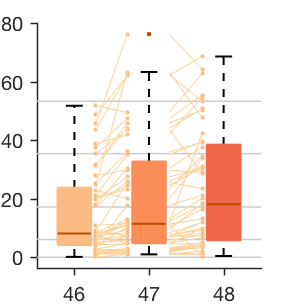


% LMS scale: 
% 0, no sensation; 1.4, barely detectable; 
% 6.1, weak; 17.2, moderate; 35.4, strong; 
% 53.3, very strong; 100, strongest imaginable sensation

create_figure('plot');
set(gcf, 'Position', [1   511   253   194]);

data = [pl.rating_int{1} pl.rating_int{2} pl.rating_int{3}]*100;

cols = [0.9922    0.7333    0.5176
    0.9882    0.5529    0.3490
    0.9373    0.3961    0.2824];

cols_dot = [0.9922    0.7314    0.5196];
cols_line = [0.9922    0.8314    0.6196];

close all;

anchors = [0 6.1 17.2 35.4 53.3];
boxplot_wani_2016(data, 'color', cols, 'linewidth', 2, 'boxlinewidth', 3, ...
    'refline', anchors, 'reflinestyle', '-', 'reflinecolor', [.8 .8 .8]);
% set(gcf, 'position',  [1   512   268   194]);
set(gcf, 'position', [1   399   288   306]);
set(gca, 'fontsize', 20, 'xlim', [0.5 3.5], 'linewidth', 1.5, 'ticklength', [.03 .03], 'xticklabel', 46:48);

xdot{1} = ones(48,1)*1+.29;
xdot{2} = ones(48,1)*2-.29;
xdot{3} = ones(48,1)*2+.27;
xdot{4} = ones(48,1)*3-.29;

scatter(xdot{1}, data(:,1), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{2}, data(:,2), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
% scatter(xdot{3}, data(:,2), 15, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{4}, data(:,3), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);

h1 = line([xdot{1} xdot{2}]', data(:,1:2)', 'color', cols_line, 'linewidth', 1);
h2 = line([xdot{3} xdot{4}]', data(:,2:3)', 'color', cols_line, 'linewidth', 1);
% for i = 1:48, h1(i).Color(4) = .5; h2(i).Color(4) = .8; end

savename = fullfile(figdir, 'Study2_pain_ratings.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

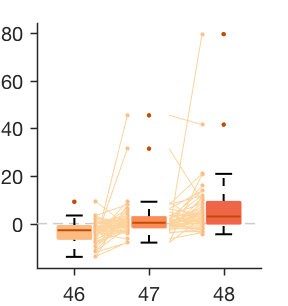

data = [pl.test_scr_int{1} pl.test_scr_int{2} pl.test_scr_int{3}];

cols = [0.9922    0.7333    0.5176
    0.9882    0.5529    0.3490
    0.9373    0.3961    0.2824];

cols_dot = [0.9922    0.7314    0.5196];
cols_line = [0.9922    0.8314    0.6196];

close all;

boxplot_wani_2016(data, 'color', cols, 'linewidth', 2, 'boxlinewidth', 3, ...
    'refline', 0, 'reflinestyle', '--', 'reflinecolor', [.8 .8 .8]);
% set(gcf, 'position',  [1   512   268   194]);
set(gcf, 'position', [1   399   288   306]);
set(gca, 'fontsize', 20, 'xlim', [0.5 3.5], 'linewidth', 1.5, 'ticklength', [.03 .03], 'xticklabel', 46:48);

xdot{1} = ones(48,1)*1+.29;
xdot{2} = ones(48,1)*2-.29;
xdot{3} = ones(48,1)*2+.27;
xdot{4} = ones(48,1)*3-.29;

scatter(xdot{1}, data(:,1), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{2}, data(:,2), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
% scatter(xdot{3}, data(:,2), 15, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{4}, data(:,3), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);

h1 = line([xdot{1} xdot{2}]', data(:,1:2)', 'color', cols_line, 'linewidth', 1);
h2 = line([xdot{3} xdot{4}]', data(:,2:3)', 'color', cols_line, 'linewidth', 1);
% for i = 1:48, h1(i).Color(4) = .5; h2(i).Color(4) = .8; end

ylim_main = get(gca, 'ylim');

savename = fullfile(figdir, 'Study2_predicted_pain.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

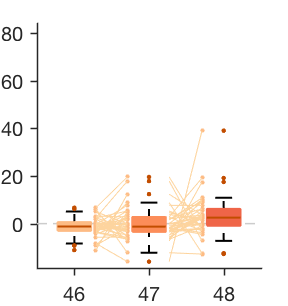

data = [pl.test_partner{1} pl.test_partner{2} pl.test_partner{3}];

cols = [0.9922    0.7333    0.5176
    0.9882    0.5529    0.3490
    0.9373    0.3961    0.2824];

cols_dot = [0.9922    0.7314    0.5196];
cols_line = [0.9922    0.8314    0.6196];

close all;

boxplot_wani_2016(data, 'color', cols, 'linewidth', 2, 'boxlinewidth', 3, ...
    'refline', 0, 'reflinestyle', '--', 'reflinecolor', [.8 .8 .8]);
% set(gcf, 'position',  [1   512   268   194]);
set(gcf, 'position', [1   399   288   306]);
set(gca, 'fontsize', 20, 'xlim', [0.5 3.5], 'ylim', ylim_main, 'linewidth', 1.5, 'ticklength', [.03 .03], 'xticklabel', 46:48);

xdot{1} = ones(42,1)*1+.29;
xdot{2} = ones(42,1)*2-.29;
xdot{3} = ones(42,1)*2+.27;
xdot{4} = ones(42,1)*3-.29;

scatter(xdot{1}, data(:,1), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{2}, data(:,2), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
% scatter(xdot{3}, data(:,2), 15, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);
scatter(xdot{4}, data(:,3), 20, cols_dot, 'filled'); %, 'MarkerFaceAlpha', .5);

h1 = line([xdot{1} xdot{2}]', data(:,1:2)', 'color', cols_line, 'linewidth', 1);
h2 = line([xdot{3} xdot{4}]', data(:,2:3)', 'color', cols_line, 'linewidth', 1);
% for i = 1:48, h1(i).Color(4) = .5; h2(i).Color(4) = .8; end

savename = fullfile(figdir, 'Study2_predicted_pain_partner.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);

close all;
create_figure('roc_plot');
% set(gcf, 'position', [360   383   374   315]);

cols = [163 41 126;
    220 82 124;
    235 155 143]/255;

contrast = [1 3; 1 2; 2 3];
clear h1 h2;

for i = 1:3
    hold on;
    h1{i} = roc_plot([pl.test_scr_int{contrast(i,1)};pl.test_scr_int{contrast(i,2)}], [false(48,1);true(48,1)], 'twochoice');
    h1{i}.line_handle(1).Color = cols(i,:);
    h1{i}.line_handle(2).Color = cols(i,:);
end

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 92% CI(85%-98%)	Spec:	 92% CI(85%-98%)	PPV:	 92% CI(84%-98%)	Nonparametric AUC:	0.96	Parametric d_a:	0.99	  Accuracy:	 92% +- 4.0% (SE), P = 0.000000


ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 81% CI(72%-90%)	Spec:	 81% CI(71%-89%)	PPV:	 81% CI(72%-90%)	Nonparametric AUC:	0.90	Parametric d_a:	0.76	  Accuracy:	 81% +- 5.6% (SE), P = 0.000015


ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 73% CI(62%-83%)	Spec:	 73% CI(62%-84%)	PPV:	 73% CI(62%-84%)	Nonparametric AUC:	0.79	Parametric d_a:	0.50	  Accuracy:	 73% +- 6.4% (SE), P = 0.002088


    
for i = 1:3
    hold on;
    h2{i} = roc_plot([pl.test_partner{contrast(i,1)};pl.test_partner{contrast(i,2)}], [false(42,1);true(42,1)], 'twochoice');
    h2{i}.line_handle(1).Color = cols(i,:);
    h2{i}.line_handle(2).Color = cols(i,:);
    h2{i}.line_handle(2).LineStyle = '--';
end

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 71% CI(59%-83%)	Spec:	 71% CI(60%-82%)	PPV:	 71% CI(60%-82%)	Nonparametric AUC:	0.80	Parametric d_a:	0.64	  Accuracy:	 71% +- 7.0% (SE), P = 0.007916


ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 50% CI(38%-64%)	Spec:	 50% CI(37%-63%)	PPV:	 50% CI(37%-63%)	Nonparametric AUC:	0.56	Parametric d_a:	0.20	  Accuracy:	 50% +- 7.7% (SE), P = 1.000000


ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 67% CI(55%-78%)	Spec:	 67% CI(54%-79%)	PPV:	 67% CI(55%-78%)	Nonparametric AUC:	0.71	Parametric d_a:	0.38	  Accuracy:	 67% +- 7.3% (SE), P = 0.043559



h3{1} = roc_plot([pl.rating_int{1};pl.rating_int{3}], [false(48,1);true(48,1)], 'twochoice');

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 96% CI(91%-100%)	Spec:	 96% CI(90%-100%)	PPV:	 96% CI(90%-100%)	Nonparametric AUC:	0.97	Parametric d_a:	1.49	  Accuracy:	 96% +- 2.9% (SE), P = 0.000000


h3{2} = roc_plot([pl.rating_int{1};pl.rating_int{2}], [false(48,1);true(48,1)], 'twochoice');

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 83% CI(74%-92%)	Spec:	 83% CI(74%-92%)	PPV:	 83% CI(74%-92%)	Nonparametric AUC:	0.92	Parametric d_a:	0.97	  Accuracy:	 83% +- 5.4% (SE), P = 0.000003


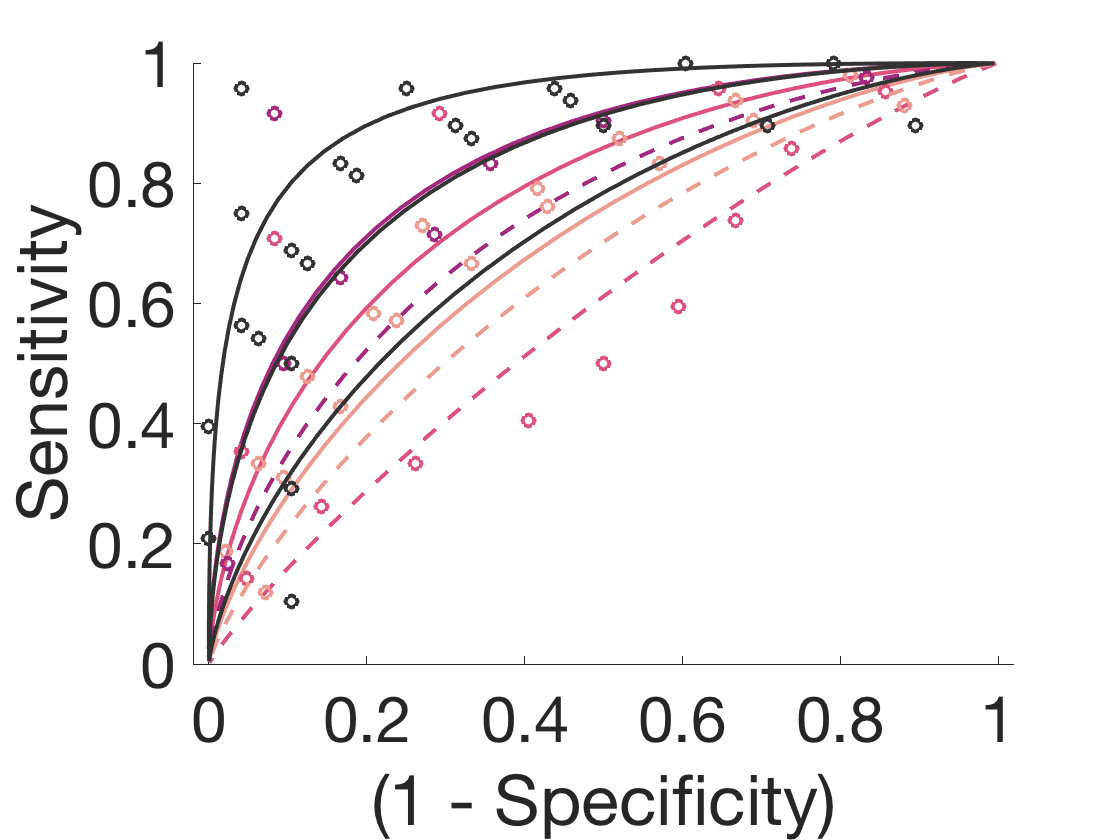

ROC for two-choice classification of paired observations.
Assumes pos and null outcome observations have the same subject order.
Using a priori threshold of 0 for pairwise differences.

ROC_PLOT Output: Two-alternative forced choice, A priori threshold
Threshold:	0.00	Sens:	 81% CI(72%-91%)	Spec:	 81% CI(71%-91%)	PPV:	 81% CI(71%-91%)	Nonparametric AUC:	0.81	Parametric d_a:	0.56	  Accuracy:	 81% +- 5.6% (SE), P = 0.000015


h3{3} = roc_plot([pl.rating_int{2};pl.rating_int{3}], [false(48,1);true(48,1)], 'twochoice');

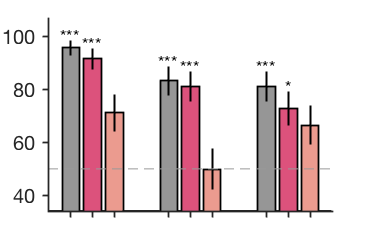

y = [h3{1}.accuracy h1{1}.accuracy h2{1}.accuracy;
    h3{2}.accuracy h1{2}.accuracy h2{2}.accuracy;
    h3{3}.accuracy h1{3}.accuracy h2{3}.accuracy]*100;

e = [h3{1}.accuracy_se h1{1}.accuracy_se h2{1}.accuracy_se;
    h3{2}.accuracy_se h1{2}.accuracy_se h2{2}.accuracy_se;
    h3{3}.accuracy_se h1{3}.accuracy_se h2{3}.accuracy_se]*100;

p = [h3{1}.accuracy_p h1{1}.accuracy_p h2{1}.accuracy_p;
    h3{2}.accuracy_p h1{2}.accuracy_p h2{2}.accuracy_p;
    h3{3}.accuracy_p h1{3}.accuracy_p h2{3}.accuracy_p]*9; % bon ferroni

cols = [150 150 150;
    220 82 124;
    235 155 143]/255;

h = bar_wani_2016(y, e, .8,  'errbar_width', 0, 'ast', p, 'colors', cols, 'ast_adj_y_pos', .2);
line(get(gca, 'xlim'), [50 50], 'color', [.6 .6 .6], 'linestyle', '--', 'linewidth', 1);
xtickbar = get(gca, 'XTick');
set(gca, 'ticklength', [.02 .02], 'xtick', xtickbar([2 5 8]));
set(gcf, 'position', [1   463   367   237]);

savename = fullfile(figdir, 'Study2_accuracy_bar.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename);